# Actividad 1.10 (SLAM de Lidar)

### Figura 2 y ejercicio 3

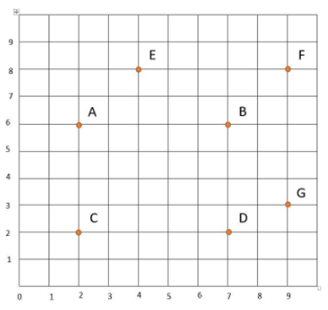

## Example Map

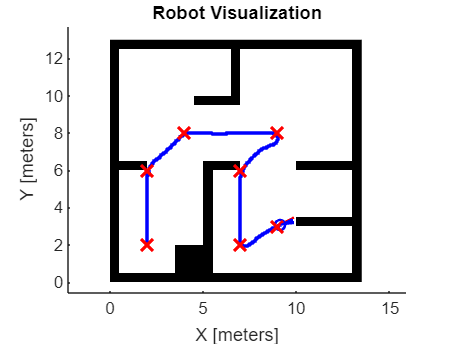

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.
%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:21;        % Time array

% Initial conditions
initPose = [2;2;pi/2];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap
% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 1;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 6;
             4 8;
             9 8;
             7 6;
             7 2;
             9 3];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 20;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.025 1]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Para este ejemplo se optó por modifcar el angulo incial del robot, así como modificar el valor de DistanceLimits, con un rango de 0.025 a 1, de esta manera se encontró que el desempeño del robot fue adecuado para recorrer las coordenadas establecidas sin colisionar con las paredes del mapa. 

## Complex Map

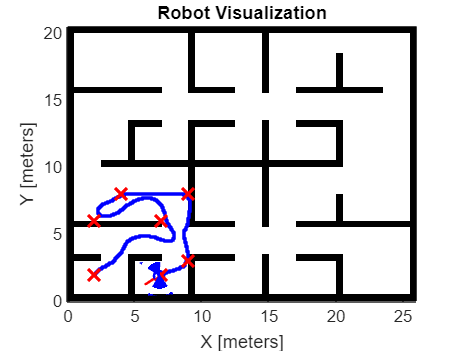

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.
%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:30;        % Time array

% Initial conditions
initPose = [2;2;pi/4];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
%load exampleMap
load complexMap
% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 1.75;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             7 6;
             2 6;
             4 8;
             9 8;
             9 3;
             7 2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.75;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 25;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.1 1.25]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Para el ejemplo del mapa complejo, se optó por modificar las siguientes varaibles:

Ángulo inicial de 45°, rango del LIDAR a 1.75, LookaheadDistance de 0.75, velocidad angular máxima de 25, así como un ajuste de DistanceLimits a [0.1 1.25].

Encontramos que los ajustes que más influían al desempeño del robot fue el ajuste de las variables del LIDAR, así como las variables de colisión, ya que se encontró que estas eran las que más influenciaban la trayectoria, dada la cercania de muchos puntos con las paredes del mapa.

Implementación para el seguimiento de los siguientes waypoints de forma secuencial: **(1, 2), (2, 10), (11, 8), (8, 2), y (1, 2)**

## Example Map

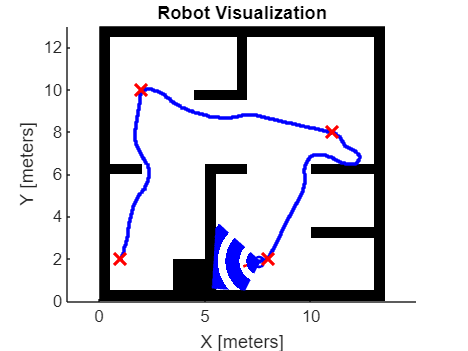

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:28;        % Time array

% Initial conditions
initPose = [1;2;pi/4];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(3*-pi/4,pi/4,200);%51
lidar.maxRange = 2.8;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 10;
             11 8;
             8 2;
             1 2;];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 20;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 2.5]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Para el ejemplo del mapa complejo, se optó por modificar las siguientes varaibles:

Ángulo inical de 45°, ajuste del lidar de 3*-pi/4 a pi/4, Lidar maxRange de 2.8.

En este ejemplo no se encontró necesario modificar otras varaibles para el correcto seguimiento de la trayectoria del robot, ya que se encontró que únicamente ajustando el campo de visión del LIDAR, así como su distancia de detección máxima fue suficiente para que este sea capaz de seguir la trayectoria con los puntos especificados.

## Complex Map

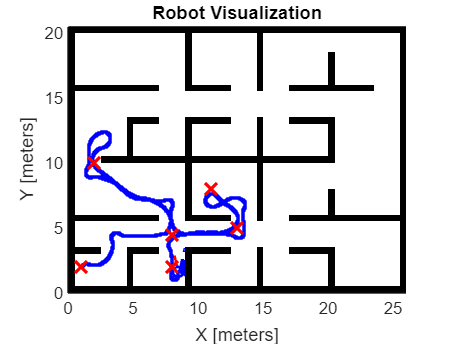

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.05;              % Sample time [s]
tVec = 0:sampleTime:119;        % Time array

% Initial conditions
initPose = [1;2;pi/4];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
%load exampleMap
load complexMap
% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-6/8*pi,3*pi/8,200);%51
lidar.maxRange = 2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
% Create waypoints
waypoints = [initPose(1:2)';
             8 4.5;
             2 10;
             8 4.5;
             13 5;
             11 8;
             13 5;
             8 4.5;
             8 2;];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.9;%0.5
controller.DesiredLinearVelocity = 0.5; %0.75
controller.MaxAngularVelocity = 25;

% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.025 2.4]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Para este ejemplo se enontró gran dificultad para que el robot recorriera de manera satisfactoria las coordenadas planteadas sin colisionar o atravesar las paredes del mapa, por lo que se tuvo que recurrir a establecer coordenadas intermedias en las principales intersecciones que debe recorrer el robot para que este pudiera seguir de manera ssatisfactoria los puntos sin colisionar, de igual manera se recurrio a ajustar los siguientes parámetros:

Ángulo incial de 45°, ajuste de LIDAR de -6/8*pi a 3*pi/8, rango máximo de 2, coordenadas intermedias [8, 4.5] y [13, 5], LookaheadDistance de 0.9, DesiredLinearVelocity de 0.5, velocidad angular máxima de 25 y distancias limite de [0.025 2.4]

Estos valores se obtuvieron de realizar diferentes pruebas y ajustes al robot de manera que mejor siguiera la trayectoria planteada.